# 5 bars painting robot

### Robot characteristic

%Definizione delle caratteristiche del robot
clc 
clear all
close all
set(0, 'DefaultFigureRenderer', 'painters');
load_robot_specs

P1 = [-0.5 0.75 h-0.2]; % Home position
P2 = [-0.25 1.1 h-0.1];
P3 = [-0.25 1.1 h-0.7];


### 1) P1 to P2

dS = norm(P2-P1);
[T_alfa,l1_alfa,l3_alfa] = minActuationTime(acc_limits(1,1),acc_limits(1,2),vel_limits(1,1),dS);
[T_beta,l1_beta,l3_beta] = minActuationTime(acc_limits(1,3),acc_limits(1,4),vel_limits(1,3),dS);
[T_rho,l1_rho,l3_rho] = minActuationTime(acc_limits(1,5),acc_limits(1,6),vel_limits(1,5),dS);

switch max([T_alfa T_beta T_rho])
    case T_alfa
        T=T_alfa; lamda1=l1_alfa; lamda3=l3_alfa;
    case T_beta
        T=T_beta; lamda1=l1_beta; lamda3=l3_beta;
    case T_rho
        T=T_rho;  lamda1=l1_rho;  lamda3=l3_rho;
end

n = 50;
dT = T/(n-1);

Q_1 = inverse_kinematics(P1,L,[130*pi/180 50*pi/180]);
Q_2 = inverse_kinematics(P2,L,[130*pi/180 50*pi/180]);

dQ = Q_2 - Q_1;

for i = 1:n
    t = (i-1)*dT;
    tt_1(i) = t;
    [q_1(i,:) qp_1(i,:) qpp_1(i,:)] = tretratti(t,T,Q_1,dQ,lamda1,lamda3);
    if i==1; guess = [0 80]; else; guess = s_1(i-1,:); end
    s_1(i,:) = direct_kinematics(q_1(i,:),L,guess);    
end


### 2) Circular trajectory

R = 0.5; dH = 0.1;
P0 = [l0/2 1.1 h-0.1];
v_cost = 2;
[s_2, v, a, dt] = trajectory_planning(R,dH,50,P0,v_cost);

for i = 1:1:length(s_2)

    if i==1
        guess = [130*pi/180 50*pi/180];
    else
        guess = q_2(i-1,:);
    end
    q_2(i,:) = inverse_kinematics(s_2(i,:),L,guess); 
    [J, J_s, J_q] = Jacobian(s_2(i,:),q_2(i,:),L);
    qp_2(i,:) = J*v(i,1:2)';
    qpp_2(i,:) = -inv(J_q)*((Jp_s(q_2(i,:),qp_2(i,:),v(i,1:2),L)*v(i,1:2)'+J_s*a(i,1:2)'+Jp_q(s_2(i,:),q_2(i,:),qp_2(i,:),v(i,1:2),L)*qp_2(i,:)'));    
end

qp_2(:,3)=v(:,3);
qpp_2(:,3)=a(:,3);

dt = horzcat(tt_1(end),dt);
tt_2=dt;
for i=2:length(dt)
    tt_2(i)=tt_2(i)+tt_2(i-1);
end

tt = horzcat(tt_1,tt_2);

### 3) P3 to P1

dS = norm(P3-P1);
[T_alfa,l1_alfa,l3_alfa] = minActuationTime(acc_limits(1,1),acc_limits(1,2),vel_limits(1,1),dS);
[T_beta,l1_beta,l3_beta] = minActuationTime(acc_limits(1,3),acc_limits(1,4),vel_limits(1,3),dS);
[T_rho,l1_rho,l3_rho] = minActuationTime(acc_limits(1,5),acc_limits(1,6),vel_limits(1,5),dS);

switch max([T_alfa T_beta T_rho])
    case T_alfa
        T=T_alfa; lamda1=l1_alfa; lamda3=l3_alfa;
    case T_beta
        T=T_beta; lamda1=l1_beta; lamda3=l3_beta;
    case T_rho
        T=T_rho;  lamda1=l1_rho;  lamda3=l3_rho;
end

n = 50;
dT = T/(n-1);

Q_1 = inverse_kinematics(P3,L,[130*pi/180 50*pi/180]);
Q_2 = inverse_kinematics(P1,L,[130*pi/180 50*pi/180]);

dQ = Q_2 - Q_1;

for i = 1:n
    t = (i-1)*dT;
    tt_3(i) = t;
    [q_3(i,:) qp_3(i,:) qpp_3(i,:)] = tretratti(t,T,Q_1,dQ,lamda1,lamda3);
    if i==1; guess = [0 80]; else; guess = s_3(i-1,:); end
    s_3(i,:) = direct_kinematics(q_3(i,:),L,guess); 
        
end

tt_3(1) = tt(end);
for i=2:length(tt_3)
    tt(i)=tt_3(i)+tt_3(i-1);
end

### 4) Sum of 3 pieces

q = vertcat(q_1,q_2,q_3);
qp = vertcat(qp_1,qp_2,qp_3);
qpp = vertcat(qpp_1,qpp_2,qpp_3);
s = vertcat(s_1,s_2,s_3);

save trajectory_data.mat q qp qpp tt s

### 3D Plot

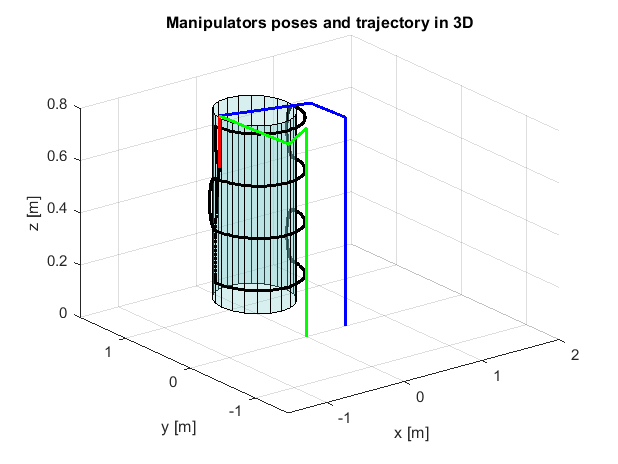

dt=0.06;
close all
figure(2)

r = 0.42;
[X,Y,Z] = cylinder(r);
Z = Z*(h-0.08);
surf(X+0.25,Y+1.1,Z,'FaceColor', [0.5,0.8,0.8]);
alpha(0.3)
xlim([-l1-l2,l0+l1+l2]);
ylim([-l1-l2,l1+1.2*l2]);
zlim([0,h]);

xlabel('x [m]')
ylabel('y [m]')
zlabel('z [m]')
title('Manipulators poses and trajectory in 3D');
grid on

for i=1:length(s)
    % Print
    [config1, theta(i)] = Plot3D_1st(q(i,:),L,2,s(i,1),s(i,2));
    [config2, gamma(i)] = Plot3D_2nd(q(i,:),L,2,s(i,1),s(i,2));
    config3 = Plot3D_3rd(L,2,s(i,1),s(i,2),s(i,3));
    plot3(s(i,1),s(i,2),s(i,3),'.-black');
    
    pause(dt)
    if i==length(s)
        break
    end
    delete(config1); delete(config2); delete(config3)
end

hold off